% shrink
shrink = load('shrinkdf.mat');
X = normalize(double(shrink.img_total));
shrinklabel = load('shrinkdf_labels.mat');
labels = shrinklabel.label;

%PCA for dim reduction
% X = X- mean(X, 1);
% k = 150;
% [U, S] = svds(X, k);
% X = U .* diag(S)'; % k principal components
% save("shrink_pca_150",'X'); % for future use
X = load('shrink_pca_150.mat');
X = X.X;

%% Laplacian Eigenmap on 8 breeds

n = size(X,1);
s = 50; % size of neighborhood (to make W row-sparse)
r = 5;

% Gaussian similarity graph
dists2 = squareform(pdist(X,'squaredeuclidean'));
dists2(1:n+1:n) = 1e100;
dists2_rnn = zeros(n,s);
idx_rnn = dists2_rnn;
for i = 1:s
    [dists2_rnn(:,i),idx_rnn(:,i)] = min(dists2,[],2);
    dists2((idx_rnn(:,i)-1)*n+(1:n)') = 1e100; 
end
sigma2 = mean(dists2_rnn(:,r));
dists2_rnn = exp(-dists2_rnn/(2*sigma2));
Gsdx = dists2_rnn ./ sum(dists2_rnn,2);
Gidx = repmat((1:n)',1,s);
Gjdx = idx_rnn;
P = sparse(Gidx(:),Gjdx(:),Gsdx(:), n, n);


% % kNN similarity graph
% [knnIDX, ~] = knnsearch(X, X, 'K', r+1);
% W = zeros(n,n);
% a = (n*(0:(n-1)))' + knnIDX(:, 2:r+1);
% W(a(:)) = 1;
% W = W';
% W = sparse(W);
% P = W ./sum(W,2);

% embedding matrix and plotting
k =8;
[V, Lambda] = eigs(P, k, 'largestreal'); 

Y = V(:,2:k); % embedding matrix

gscatter(Y(:,1), Y(:,2), labels); 

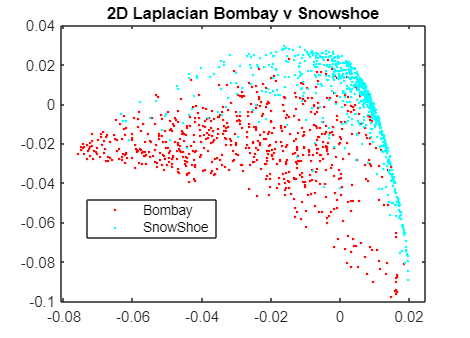

% Laplacian Eigenmap on subset
X = load('shrink_pca_150.mat');
X = X.X;
labels = shrinklabel.label;
%snowshoe, bombay
idx = logical((labels == 'SnowShoe') + (labels == "Bombay"));
X = X(idx,:);
labels = labels(idx);

n = size(X,1);
s = 50; % size of neighborhood (to make W row-sparse)
%r = 5;

% Gaussian similarity graph
dists2 = squareform(pdist(X,'squaredeuclidean'));
dists2(1:n+1:n) = 1e100;
dists2_rnn = zeros(n,s);
idx_rnn = dists2_rnn;
for i = 1:s
    [dists2_rnn(:,i),idx_rnn(:,i)] = min(dists2,[],2);
    dists2((idx_rnn(:,i)-1)*n+(1:n)') = 1e100; 
end
sigma2 = mean(dists2_rnn(:,r));
dists2_rnn = exp(-dists2_rnn/(2*sigma2));
Gsdx = dists2_rnn ./ sum(dists2_rnn,2);
Gidx = repmat((1:n)',1,s);
Gjdx = idx_rnn;
P = sparse(Gidx(:),Gjdx(:),Gsdx(:), n, n);


% % kNN similarity graph
% [knnIDX, ~] = knnsearch(X, X, 'K', r+1);
% W = zeros(n,n);
% a = (n*(0:(n-1)))' + knnIDX(:, 2:r+1);
% W(a(:)) = 1;
% W = W';
% W = sparse(W);
% P = W ./sum(W,2);

% embedding matrix and plotting
%k = 8;
k = 3;
[V, Lambda] = eigs(P, k, 'largestreal'); 

Y = V(:,2:k); % embedding matrix

gscatter(Y(:,1), Y(:,2), labels); 
%title("2D Embedding 8 Breeds");
%saveas(gcf, '2D Embedding 8 Breeds Laplacian.png');
title("2D Laplacian Bombay v Snowshoe")
saveas(gcf, "Bombay vs SnowShow Laplacian_shrink.png");

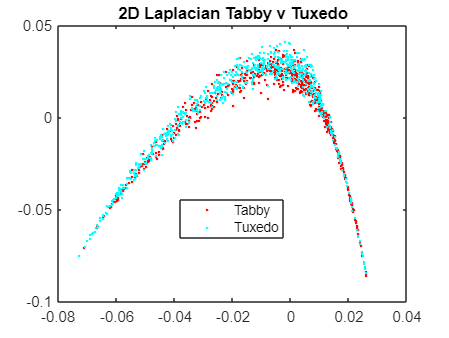

%check all pairwise
X = load('shrink_pca_150.mat');
X = X.X;
labels = shrinklabel.label;
breeds = unique(labels);
for i = 1:length(breeds)
    for j = 1:length(breeds)
        if i >= j
            continue
        end
        
        breed1 = breeds(i);
        breed2 = breeds(j);
        idx = logical((labels == breed1) + (labels == breed2));
        loopX = X(idx,:);
        looplabels = labels(idx);

        n = size(loopX,1);
        s = 50; % size of neighborhood (to make W row-sparse)
        %r = 5;

        % Gaussian similarity graph
        dists2 = squareform(pdist(loopX,'squaredeuclidean'));
        dists2(1:n+1:n) = 1e100;
        dists2_rnn = zeros(n,s);
        idx_rnn = dists2_rnn;
        for p = 1:s
            [dists2_rnn(:,p),idx_rnn(:,p)] = min(dists2,[],2);
            dists2((idx_rnn(:,p)-1)*n+(1:n)') = 1e100;
        end
        sigma2 = mean(dists2_rnn(:,r));
        dists2_rnn = exp(-dists2_rnn/(2*sigma2));
        Gsdx = dists2_rnn ./ sum(dists2_rnn,2);
        Gidx = repmat((1:n)',1,s);
        Gjdx = idx_rnn;
        P = sparse(Gidx(:),Gjdx(:),Gsdx(:), n, n);

        % embedding matrix and plotting
        %k = 8;
        k = 3;
        [V, Lambda] = eigs(P, k, 'largestreal');

        Y = V(:,2:k); % embedding matrix

        gscatter(Y(:,1), Y(:,2), looplabels);

        t = strcat(strcat(strcat("2D Laplacian ", breed1), " v "), breed2);
        title(t);
        s = strcat(strcat(strcat(breed1, " vs "), breed2), " Laplacian_shrink.png");
        saveas(gcf, s);
    end
end

for i = 1:length(breeds)
    breed1 = breeds(i);
    for j = 1:length(breeds)
        if i >= j
            continue
        end
        breed2 = breeds(j);
        [breed1, breed2]
    end
end

ans = 1×2 string array
    "Bengal"    "Bombay"


ans = 1×2 string array
    "Bengal"    "Himalayan"


ans = 1×2 string array
    "Bengal"    "Maine_Coon"


ans = 1×2 string array
    "Bengal"    "Russian_Blue"


ans = 1×2 string array
    "Bengal"    "SnowShoe"


ans = 1×2 string array
    "Bengal"    "Tabby"


ans = 1×2 string array
    "Bengal"    "Tuxedo"


ans = 1×2 string array
    "Bombay"    "Himalayan"


ans = 1×2 string array
    "Bombay"    "Maine_Coon"


ans = 1×2 string array
    "Bombay"    "Russian_Blue"


ans = 1×2 string array
    "Bombay"    "SnowShoe"


ans = 1×2 string array
    "Bombay"    "Tabby"


ans = 1×2 string array
    "Bombay"    "Tuxedo"


ans = 1×2 string array
    "Himalayan"    "Maine_Coon"


ans = 1×2 string array
    "Himalayan"    "Russian_Blue"


ans = 1×2 string array
    "Himalayan"    "SnowShoe"


ans = 1×2 string array
    "Himalayan"    "Tabby"


ans = 1×2 string array
    "Himalayan"    "Tuxedo"


ans = 1×2 string array
    "Maine_Coon"    "Russian_Blue"


ans = 1×2 string array
    "Maine_Coon"    "SnowShoe"


ans = 1×2 string array
    "Maine_Coon"    "Tabby"


ans = 1×2 string array
    "Maine_Coon"    "Tuxedo"


ans = 1×2 string array
    "Russian_Blue"    "SnowShoe"


ans = 1×2 string array
    "Russian_Blue"    "Tabby"


ans = 1×2 string array
    "Russian_Blue"    "Tuxedo"


ans = 1×2 string array
    "SnowShoe"    "Tabby"


ans = 1×2 string array
    "SnowShoe"    "Tuxedo"


ans = 1×2 string array
    "Tabby"    "Tuxedo"
